# Kinetics, Bioreactors, and Chemostats (CSTR)

## Computational Tools Needed

MATLAB, Symbolic Math Toolbox

## Learning Objectives

- Using Symbolic Math Toolbox to obtain symbolic expressions reaction kinetics.

- Using MATLAB's ODE Solvers and "Solve ODE" Live Task to integrate rate equations in a batch bioreactor and visualize results

## Monod Equation

Typically, the growth of cells in a bioreactor can be summarized as 


$$\textrm{Cells}+\textrm{Substrate}\to \textrm{More}\;\textrm{cells}+\textrm{Product}\;$$


For exponential growth, Monod equation is the most commonly used expression:

$r_g =\mu C_C$                                              **(Equation 1)**

The specific cell growth rate is given by:

$\mu =\mu_{\max } \frac{C_s }{K_s +C_s }\;$                                  **(Equation 2)**

 **Exercise 1: **

Using MATLAB's Symbolic Math Toolbox, symbolically define Equation 1 and 2 in MATLAB, substitute Equation 2 into Equation 1 to derive **Monod Equation.**

% write your code here 

%Solution
syms mu Cc rg Cs Ks mu_max

% Define the equations
eq1 = rg == mu * Cc;
eq2 = mu == mu_max * Cs / (Ks + Cs);

% Substitute equation 2 into equation 1
monod_eq = subs(eq1, mu, rhs(eq2));

disp(monod_eq)

$$\mathrm{rg}=\frac{\mathrm{Cc}\,\mathrm{Cs}\,\mu_{\max}}{\mathrm{Cs}+\mathrm{Ks}}$$

## Bacteria Growth in a Batch Reactor

Glucose fermentation to ethanol is achieved in a batch reactor using Saccharomyces cerevisiae. 

- Batch reactor with a constant volume, V 

- Flow rates into the reactor and out of the reactor are equal to 0. 

- Growth rate with inhibition

Mass balances for this case are as follows:

**Cell: **

$\frac{dC_c }{\textrm{dt}}=$ $\mu_{\max } \frac{C_c {\;C}_s }{K_s +C_s }$${\left(1-\frac{c_p }{c_p^* }\right)}^n -k_d C_c$                       **(Equation 3)**

**Substrate (growth phase)**

$\frac{dC_s }{\textrm{dt}}={-Y}_{s|c} \;\mu_{\max } \frac{C_c {\;C}_s }{K_s +C_s }{\left(1-\frac{c_p }{c_p^* }\right)}^n -{\textrm{mC}}_{c\;}$                **(Equation 4)**

**Product**

$\frac{dC_p }{\textrm{dt}}=Y_{p|c} \;\mu_{\max } \frac{C_c {\;C}_s }{K_s +C_s }{\left(1-\frac{c_p }{c_p^* }\right)}^n$                             **(Equation 5)**

 **Exercise 2: **Solve Equation 3, 4, 5 using MATLAB's [ode45 solver ](https://www.mathworks.com/help/matlab/ref/ode45.html)with the following values and plot the concentration of the cells, $C_c$, substrate $C_s$, product $C_p$ vs. time.

% Initial Conditions for the differential equations

Cc0=5

Cc0 = 5

Cs0= 250

Cs0 = 250

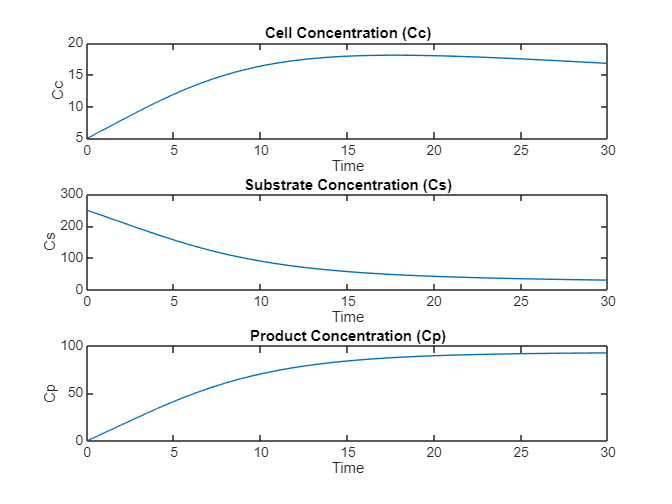

Cp0=0;


% Solution

% Time span
tspan = [0 30]; % Adjust the time span as needed

% ODE function
function dYdt = odefun(t, Y)
    Cc = Y(1);
    Cs = Y(2);
    Cp = Y(3);
    % Values of the parameters
    Cpstar=93;
    n=0.52;
    Ysc=1/0.08;
    Ypc=5.6;
    mumax=0.33;
    Ks=1.7;
    kd=0.01;
    m=0.03;
    
    rg = mumax * (Cc * Cs / (Ks + Cs)) * (1 - (Cp / Cpstar)^n);
    
    dCc_dt = rg - kd * Cc;
    dCs_dt = -Ysc * rg - m * Cc;
    dCp_dt = Ypc * rg;
    
    dYdt = [dCc_dt; dCs_dt; dCp_dt];
end

% Solve ODE
InitialCondition=[Cc0, Cs0, Cp0];
[t, Y] = ode45(@odefun, tspan, InitialCondition);

% Plot results
figure;
subplot(3,1,1);
plot(t, Y(:,1));
title('Cell Concentration (Cc)');
xlabel('Time');
ylabel('Cc');

subplot(3,1,2);
plot(t, Y(:,2));
title('Substrate Concentration (Cs)');
xlabel('Time');
ylabel('Cs');

subplot(3,1,3);
plot(t, Y(:,3));
title('Product Concentration (Cp)');
xlabel('Time');
ylabel('Cp');


figure

  ** Try: **

- What happens if you change the initial cell and substrate conditions?

- What happens if you change the timespan for the ODE solution?

- What happens if you use different ODE solvers? You can explore other ODE solvers [here.](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

**Exercise 3: **Solve the same problem using "Solve ODE" Live Task in the Live Editor. To add this Live Task, on Live Editor tab, click on "Task" dropdown and serch for "Solve ODE".

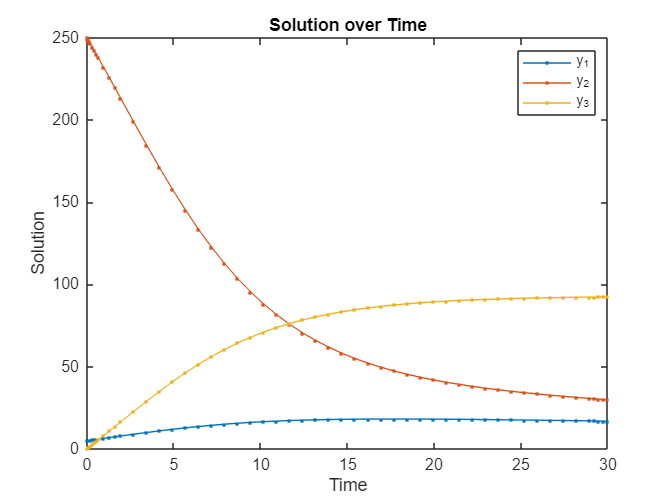

% Define ODE problem and specify solver options
odeObj = ode(ODEFcn = @odefun, ...
    InitialValue = InitialCondition);

% Solve ODE problem
solData = solve(odeObj,0,30);

% Plot solution over time
plot(solData.Time,solData.Solution([1 2 3],:),".-");
ylabel("Solution")
xlabel("Time")
title("Solution over Time")
legend("y_1","y_2","y_3")

clear odeObj

## **Chemostats (CSTR)**

- Let's consider the same problem, but this time, we will allow constant feed flow rate $\nu_{0\;}$ into and out of the reactor. The reactor volume is constant at $V\ldotp$ Using these, let's define the dilution rate as: $D=\frac{\nu_{0\;} }{V}$

- If no living cells are entering the reactor, set $C_{\textrm{cin}}$ = 0.

Mass balances for this case:


$$\textrm{Accumulation}=\textrm{In}-\textrm{Out}+\textrm{Generation}\;\textrm{or}\;\textrm{Depletion}$$


**Cell:**

$\frac{{\textrm{dC}}_c }{\textrm{dt}}={\textrm{DC}}_{\textrm{cin}} -{\textrm{DC}}_{c\;} +\left(r_g -r_d \right)=D\;\left(C_{\textrm{c0}} -C_c \right)\;\;+$$\mu_{\max } \frac{C_c {\;C}_s }{K_s +C_s }$${\left(1-\frac{c_p }{c_p^* }\right)}^n -k_d C_c$                  **                         (Equation 6)**

**Substrate:**

$\frac{{\textrm{dC}}_s }{\textrm{dt}}={\textrm{DC}}_{\sin \;} -{\textrm{DC}}_s +r_s =D\left(C_{\sin } -C_s \right)+r_s =D\left(C_{\textrm{s0}} -C_s \right){-Y}_{s|c} \;\mu_{\max } \frac{C_c {\;C}_s }{K_s +C_s }{\left(1-\frac{c_p }{c_p^* }\right)}^n -{\textrm{mC}}_{c\;}$                     **(Equation 7)**

**Product: **

$\frac{{\textrm{dC}}_p }{\textrm{dt}}={-\textrm{DC}}_{p\;} +r_{p\;\;} ={-\textrm{DC}}_p +Y_{p|c} \;\mu_{\max } \frac{C_c {\;C}_s }{K_s +C_s }{\left(1-\frac{c_p }{c_p^* }\right)}^n$                             **                                                 (Equation 8)**

**Exercise 4: **Modify the ODE function code from Exercise 2 to solve the Equations 6, 7, 8 with the same parameters as Exercise 2. For dilution, add a slider that ranges from 0 to 0.6 with 0.01 increments. You should define the variable for Dilution, D, inlet substrate and cell concentrations $C_{\textrm{cin}\;} ,C_{\sin }$ and other parameters in the function where you define the differential equations.

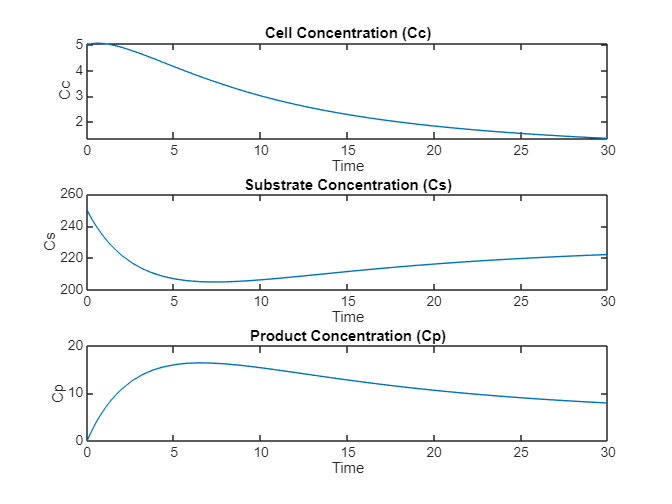


% ODE function
function dYdt = odefun1(t, Y)
D= 0.25;
    Cc = Y(1);
    Cs = Y(2);
    Cp = Y(3);
    Cpstar=93;
    n=0.52;
    Ysc=1/0.08;
    Ypc=5.6;
    mumax=0.33;
    Ks=1.7;
    kd=0.01;
    m=0.03;
    Ccin=0;
    Csin=240;
    rg = mumax * (Cc * Cs / (Ks + Cs)) * (1 - (Cp / Cpstar)^n);
    
    
    dCc_dt = D*(Ccin-Cc)+ rg - kd * Cc;
    dCs_dt = D*(Csin-Cs)-Ysc * rg - m * Cc;
    dCp_dt = -D*Cp+ Ypc * rg;
    

    dYdt = [dCc_dt; dCs_dt; dCp_dt];
end

% Solve ODE
InitialCondition=[Cc0, Cs0, Cp0];
[t, Y] = ode45(@odefun1, tspan, InitialCondition);

% Plot results
figure;
subplot(3,1,1);
plot(t, Y(:,1));
title('Cell Concentration (Cc)');
xlabel('Time');

$$eq6(t) = \frac{\partial }{\partial t}\mathrm{Cc}\left(t\right)=\mathrm{rg}-\mathrm{rd}-\text{D}\,\mathrm{Cc}\left(t\right)$$

ylabel('Cc');

subplot(3,1,2);
plot(t, Y(:,2));
title('Substrate Concentration (Cs)');
xlabel('Time');
ylabel('Cs');


$$ans(t) = \text{D}=\mu$$

subplot(3,1,3);
plot(t, Y(:,3));
title('Product Concentration (Cp)');
xlabel('Time');
ylabel('Cp');


  ** Try: **

- What happens if you change the initial cell and substrate conditions? 

- What happens if you change the inlet cell and substrate concentrations?

- If you set D=0 i.e. no flow, do you get the same results as Exercise 2 and 3 results? 

- What happens if the dilution rate, D is high? What happens if the dilution rate, D is low?  

- What happens if the cell death rate is 0?

**Exercise 5: **Define Equation 6  symbolically (first part, i.e. $\frac{{\textrm{dC}}_c }{\textrm{dt}}=-{\textrm{DC}}_{c\;} +\left(r_g -r_d \right)$ with no living cells entering) using MATLAB's Symbolic Math Toolbox.Then, assume that it is a steady-state operation, i.e. $\frac{{\textrm{dC}}_c }{\textrm{dt}}=0$. Assume death rate, $r_d$ is 0.Use $r_g =\mu \;C_c$  for cell growth. How is dilution, D related to the specific growth rate, $\mu \;$? 

% Write your code here

% Solution

syms D rd t Cc(t) rg mu
% Define equations
eq6= diff(Cc, t)==-D*Cc+rg-rd

% Steady-state versions of the equations (set derivatives to zero)
eq6_ss = subs(eq6, diff(Cc, t), 0);

eq6_ss=subs(eq6_ss,rd,0);
eq6_ss=subs(eq6_ss, rg, mu*Cc);
assume(Cc(t)~=0)
simplify(eq6_ss)


### **Things to Consider:**

- At steady-state, $D=\mu \;$i.e. the specific growth rate of the cells can be controlled by controlling the dilution rate, $D=\frac{\nu_{0\;} }{V}$ 

- If the dilution rate is increased such that $D>\mu \;$, eventually, there will be a point where $C_c =0$, that's called **wash-out.  **The other extreme for the dilution rate is when the rate of cell production is maximum.

## **References**

[1] Fogler, H. Scott. Elements of Chemical Reaction Engineering. Prentice Hall, 2006.

[2][ Fogler, H. Scott Lecture Notes ](https://websites.umich.edu/~elements/6e/lectures/umich.html)